clc
clear all
format long g
% Template for assignment 1, advanced part
% ----------------------------------------------
% INPUTS
% ------

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%55
NELEM = 100 ;  % Number of elements
nsteps = 101 ;  % Number of steps
stepsPOST = [1:5:nsteps]; % Steps to post-process


A0 = 1e-2; %m  % Reference AREA
E0 = 10 ; % MPa  % Reference Young's Modulus
sigma_0 = 1; %MPa  % Saturation stress
L = 1 ;%m    % Length of the beam
T = 1; % s Final time
um = 0.2*L; %m   % Maximum displacement
AreaFUN = @(x) (A0*(1+2*(x/L).*(x/L-1)))  ;  % Area as a function of the distance from the left end
stressFUN = @(strain) (sigma_0*(1-exp(-E0/sigma_0*strain))) ;  % Constitutive equation (stress versus strain)
DerStressFUN = @(strain) (E0*exp(-E0/sigma_0*strain)) ;  % Tangent modulus (Derivative of the stress with respect to the strain)
r = [1,NELEM+1]  ; % Indexes Prescribed DOF  %
uEND = @(t) (t/T*um);  %  Non-zero prescribed displacement, as a function of time
TOL_residual = 1e-6;  % Convergence tolerance for the Newton-Raphson
MAXITER = 50 ;  % Maximum number of iterations  for the Newton-Raphson
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%% END INPUTS % ------------------------------------------
% MESH INFORMATION
nnode = NELEM+1 ;
COOR = linspace(0,L,nnode)' ;
CN = [(1:(nnode-1))',(2:nnode)'] ;
l = setdiff([1:nnode],r) ;

d = zeros(nnode,1) ;  % Displacement at time tn

TIMES = linspace(0,T,nsteps) ;

% STORE INFORMATION for post-processing purpose
% -----------------------
STRESS_GLO = zeros(NELEM,nsteps) ;
STRAIN_GLO  = zeros(NELEM,nsteps) ;
d_GLO  = zeros(nnode,length(stepsPOST)) ;

iplot = 1;



for istep=1:nsteps
    t = TIMES(istep) ;  % Time
    d(nnode) = uEND(t) ;    
    
    disp(['Number of  step = ',num2str(istep), ', Time = ',num2str(t),', uEND =  ',num2str( uEND(t)) ])
    disp('********************************************************************')
    % Boundary conditions
    %-------------------
    % Compute the vector of internal forces = residual
    % as a function of the nodal displacement n
    
    % Solution of the equations Residual(d) = 0     via Newton-Raphson
    % algoritm
    d_k = d; %   nodal displacements at iteration k
    k = 0 ; % Number of iteration
    while  k <= MAXITER
        % ASsembly the residual vector (= internal forces)
        [Residual,STRAIN,STRESS] = AssemblyFint(COOR,CN,d_k,stressFUN,AreaFUN) ;
        normRESIDUAL = norm(Residual(l)) ; % Euclidean norm residual
        disp(['k = ',num2str(k),' res=',num2str(normRESIDUAL),', MAX strain = ',num2str(max(STRAIN)),', MAX stress = ',num2str(max(STRESS))])
        if normRESIDUAL < TOL_residual
            % Convergence
            d = d_k ;
            break
        end
        % The norm of the residual is greater than the prescribed
        % tolerance.  This means that equilibrium is not met
        % Let us calculate the new displacement vector
        
        % Compute the Jacobian of the system of equations
        K = AssemblyKnon(COOR,CN,d_k,AreaFUN,DerStressFUN);
            Delta_d_l = -K(l,l)\Residual(l) ;
        d_k(l) = d_k(l) + Delta_d_l;
        k = k +1 ;
    end
    
    if  k >  MAXITER
        error('The Newtown-R. algorithm has failed to converge')
    else
        d=d_k ;
        d_GLO(:,iplot) = d ;
        STRAIN_GLO(:,iplot) = STRAIN ;
        STRESS_GLO(:,iplot) = STRESS ;
        iplot = iplot +1 ;
    end
end

Number of  step = 1, Time = 0, uEND =  0


********************************************************************


k = 0 res=0, MAX strain = 0, MAX stress = 0


Number of  step = 2, Time = 0.01, uEND =  0.002


********************************************************************


k = 0 res=0.0085606, MAX strain = 0.2, MAX stress = 0.86466
k = 1 res=0.58638, MAX strain = 0.0078129, MAX stress = 0.075155
k = 2 res=0.21319, MAX strain = 0.0065906, MAX stress = 0.063781
k = 3 res=0.075937, MAX strain = 0.0053508, MAX stress = 0.052101
k = 4 res=0.025564, MAX strain = 0.0042049, MAX stress = 0.041177
k = 5 res=0.0073579, MAX strain = 0.0032716, MAX stress = 0.032186
k = 6 res=0.0013692, MAX strain = 0.0027197, MAX stress = 0.02683
k = 7 res=7.9941e-05, MAX strain = 0.0025625, MAX stress = 0.0253
k = 8 res=3.1929e-07, MAX strain = 0.0025522, MAX stress = 0.025199


Number of  step = 3, Time = 0.02, uEND =  0.004


********************************************************************


k = 0 res=0.0084516, MAX strain = 0.20128, MAX stress = 0.86638
k = 1 res=0.58012, MAX strain = 0.010404, MAX stress = 0.098809
k = 2 res=0.21092, MAX strain = 0.0091766, MAX stress = 0.087682
k = 3 res=0.075133, MAX strain = 0.0079307, MAX stress = 0.076243
k = 4 res=0.025298, MAX strain = 0.006779, MAX stress = 0.065543
k = 5 res=0.007285, MAX strain = 0.0058407, MAX stress = 0.056734
k = 6 res=0.0013575, MAX strain = 0.0052853, MAX stress = 0.051481
k = 7 res=7.9546e-05, MAX strain = 0.0051268, MAX stress = 0.049976
k = 8 res=3.2019e-07, MAX strain = 0.0051164, MAX stress = 0.049877


Number of  step = 4, Time = 0.03, uEND =  0.006


********************************************************************


k = 0 res=0.0083449, MAX strain = 0.20255, MAX stress = 0.86807
k = 1 res=0.57411, MAX strain = 0.013008, MAX stress = 0.12197
k = 2 res=0.20874, MAX strain = 0.011776, MAX stress = 0.11109
k = 3 res=0.074362, MAX strain = 0.010523, MAX stress = 0.099887
k = 4 res=0.025043, MAX strain = 0.0093659, MAX stress = 0.089407
k = 5 res=0.0072156, MAX strain = 0.0084224, MAX stress = 0.080775
k = 6 res=0.0013467, MAX strain = 0.0078634, MAX stress = 0.075622
k = 7 res=7.9223e-05, MAX strain = 0.0077035, MAX stress = 0.074143
k = 8 res=3.2162e-07, MAX strain = 0.0076929, MAX stress = 0.074044


Number of  step = 5, Time = 0.04, uEND =  0.008


********************************************************************


k = 0 res=0.0082404, MAX strain = 0.20381, MAX stress = 0.86972
k = 1 res=0.56824, MAX strain = 0.015625, MAX stress = 0.14466
k = 2 res=0.20661, MAX strain = 0.014388, MAX stress = 0.13401
k = 3 res=0.073608, MAX strain = 0.013129, MAX stress = 0.12304
k = 4 res=0.024794, MAX strain = 0.011966, MAX stress = 0.11278
k = 5 res=0.0071478, MAX strain = 0.011017, MAX stress = 0.10432
k = 6 res=0.0013361, MAX strain = 0.010454, MAX stress = 0.099263
k = 7 res=7.8914e-05, MAX strain = 0.010293, MAX stress = 0.097808
k = 8 res=3.2314e-07, MAX strain = 0.010282, MAX stress = 0.097711


Number of  step = 6, Time = 0.05, uEND =  0.01


********************************************************************


k = 0 res=0.0081381, MAX strain = 0.20506, MAX stress = 0.87134
k = 1 res=0.56249, MAX strain = 0.018256, MAX stress = 0.16687
k = 2 res=0.20453, MAX strain = 0.017014, MAX stress = 0.15645
k = 3 res=0.072871, MAX strain = 0.015749, MAX stress = 0.14571
k = 4 res=0.02455, MAX strain = 0.014579, MAX stress = 0.13566
k = 5 res=0.0070816, MAX strain = 0.013624, MAX stress = 0.12737
k = 6 res=0.0013258, MAX strain = 0.013058, MAX stress = 0.12241
k = 7 res=7.862e-05, MAX strain = 0.012895, MAX stress = 0.12098
k = 8 res=3.2474e-07, MAX strain = 0.012884, MAX stress = 0.12089


Number of  step = 7, Time = 0.06, uEND =  0.012


********************************************************************


k = 0 res=0.0080379, MAX strain = 0.2063, MAX stress = 0.87292
k = 1 res=0.55688, MAX strain = 0.020901, MAX stress = 0.18862
k = 2 res=0.20249, MAX strain = 0.019653, MAX stress = 0.17843
k = 3 res=0.07215, MAX strain = 0.018381, MAX stress = 0.16791
k = 4 res=0.024312, MAX strain = 0.017205, MAX stress = 0.15806
k = 5 res=0.007017, MAX strain = 0.016245, MAX stress = 0.14994
k = 6 res=0.0013158, MAX strain = 0.015675, MAX stress = 0.14508
k = 7 res=7.8341e-05, MAX strain = 0.015511, MAX stress = 0.14368
k = 8 res=3.2642e-07, MAX strain = 0.0155, MAX stress = 0.14358


Number of  step = 8, Time = 0.07, uEND =  0.014


********************************************************************


k = 0 res=0.0079398, MAX strain = 0.20752, MAX stress = 0.87447
k = 1 res=0.55139, MAX strain = 0.023561, MAX stress = 0.20991
k = 2 res=0.2005, MAX strain = 0.022307, MAX stress = 0.19994
k = 3 res=0.071446, MAX strain = 0.021028, MAX stress = 0.18964
k = 4 res=0.02408, MAX strain = 0.019845, MAX stress = 0.18
k = 5 res=0.0069538, MAX strain = 0.01888, MAX stress = 0.17205
k = 6 res=0.001306, MAX strain = 0.018306, MAX stress = 0.16728
k = 7 res=7.8075e-05, MAX strain = 0.01814, MAX stress = 0.1659
k = 8 res=3.2819e-07, MAX strain = 0.018128, MAX stress = 0.1658


Number of  step = 9, Time = 0.08, uEND =  0.016


********************************************************************


k = 0 res=0.0078437, MAX strain = 0.20874, MAX stress = 0.87599
k = 1 res=0.54602, MAX strain = 0.026235, MAX stress = 0.23075
k = 2 res=0.19855, MAX strain = 0.024975, MAX stress = 0.22101
k = 3 res=0.070757, MAX strain = 0.023689, MAX stress = 0.21092
k = 4 res=0.023853, MAX strain = 0.0225, MAX stress = 0.20148
k = 5 res=0.0068921, MAX strain = 0.021529, MAX stress = 0.19369
k = 6 res=0.0012965, MAX strain = 0.02095, MAX stress = 0.18901
k = 7 res=7.7824e-05, MAX strain = 0.020783, MAX stress = 0.18765
k = 8 res=3.3004e-07, MAX strain = 0.020771, MAX stress = 0.18756


Number of  step = 10, Time = 0.09, uEND =  0.018


********************************************************************


k = 0 res=0.0077496, MAX strain = 0.20995, MAX stress = 0.87748
k = 1 res=0.54078, MAX strain = 0.028923, MAX stress = 0.25116
k = 2 res=0.19665, MAX strain = 0.027658, MAX stress = 0.24163
k = 3 res=0.070084, MAX strain = 0.026365, MAX stress = 0.23176
k = 4 res=0.023631, MAX strain = 0.025169, MAX stress = 0.22251
k = 5 res=0.0068319, MAX strain = 0.024192, MAX stress = 0.21488
k = 6 res=0.0012873, MAX strain = 0.023609, MAX stress = 0.21029
k = 7 res=7.7586e-05, MAX strain = 0.02344, MAX stress = 0.20895
k = 8 res=3.3198e-07, MAX strain = 0.023428, MAX stress = 0.20886


Number of  step = 11, Time = 0.1, uEND =  0.02


********************************************************************


k = 0 res=0.0076575, MAX strain = 0.21114, MAX stress = 0.87894
k = 1 res=0.53565, MAX strain = 0.031628, MAX stress = 0.27114
k = 2 res=0.19479, MAX strain = 0.030357, MAX stress = 0.26182
k = 3 res=0.069427, MAX strain = 0.029056, MAX stress = 0.25216
k = 4 res=0.023414, MAX strain = 0.027853, MAX stress = 0.2431
k = 5 res=0.0067731, MAX strain = 0.026869, MAX stress = 0.23562
k = 6 res=0.0012783, MAX strain = 0.026282, MAX stress = 0.23112
k = 7 res=7.7362e-05, MAX strain = 0.026112, MAX stress = 0.22981
k = 8 res=3.34e-07, MAX strain = 0.0261, MAX stress = 0.22972


Number of  step = 12, Time = 0.11, uEND =  0.022


********************************************************************


k = 0 res=0.0075673, MAX strain = 0.21233, MAX stress = 0.88036
k = 1 res=0.53064, MAX strain = 0.034348, MAX stress = 0.2907
k = 2 res=0.19297, MAX strain = 0.033071, MAX stress = 0.28158
k = 3 res=0.068785, MAX strain = 0.031762, MAX stress = 0.27212
k = 4 res=0.023202, MAX strain = 0.030552, MAX stress = 0.26326
k = 5 res=0.0067158, MAX strain = 0.029562, MAX stress = 0.25593
k = 6 res=0.0012695, MAX strain = 0.028971, MAX stress = 0.25152
k = 7 res=7.7152e-05, MAX strain = 0.028799, MAX stress = 0.25023
k = 8 res=3.3611e-07, MAX strain = 0.028787, MAX stress = 0.25014


Number of  step = 13, Time = 0.12, uEND =  0.024


********************************************************************


k = 0 res=0.007479, MAX strain = 0.2135, MAX stress = 0.88176
k = 1 res=0.52575, MAX strain = 0.037084, MAX stress = 0.30984
k = 2 res=0.1912, MAX strain = 0.035801, MAX stress = 0.30093
k = 3 res=0.068157, MAX strain = 0.034485, MAX stress = 0.29167
k = 4 res=0.022995, MAX strain = 0.033267, MAX stress = 0.28299
k = 5 res=0.0066598, MAX strain = 0.032271, MAX stress = 0.27581
k = 6 res=0.001261, MAX strain = 0.031675, MAX stress = 0.27149
k = 7 res=7.6955e-05, MAX strain = 0.031501, MAX stress = 0.27022
k = 8 res=3.3831e-07, MAX strain = 0.031489, MAX stress = 0.27013


Number of  step = 14, Time = 0.13, uEND =  0.026


********************************************************************


k = 0 res=0.0073926, MAX strain = 0.21466, MAX stress = 0.88312
k = 1 res=0.52097, MAX strain = 0.039836, MAX stress = 0.32858
k = 2 res=0.18947, MAX strain = 0.038547, MAX stress = 0.31987
k = 3 res=0.067544, MAX strain = 0.037223, MAX stress = 0.3108
k = 4 res=0.022793, MAX strain = 0.035998, MAX stress = 0.30231
k = 5 res=0.0066051, MAX strain = 0.034995, MAX stress = 0.29528
k = 6 res=0.0012527, MAX strain = 0.034395, MAX stress = 0.29103
k = 7 res=7.6771e-05, MAX strain = 0.034219, MAX stress = 0.28978
k = 8 res=3.4059e-07, MAX strain = 0.034206, MAX stress = 0.2897


Number of  step = 15, Time = 0.14, uEND =  0.028


********************************************************************


k = 0 res=0.007308, MAX strain = 0.21582, MAX stress = 0.88446
k = 1 res=0.5163, MAX strain = 0.042606, MAX stress = 0.34692
k = 2 res=0.18777, MAX strain = 0.04131, MAX stress = 0.3384
k = 3 res=0.066946, MAX strain = 0.039978, MAX stress = 0.32953
k = 4 res=0.022596, MAX strain = 0.038745, MAX stress = 0.32121
k = 5 res=0.0065518, MAX strain = 0.037735, MAX stress = 0.31433
k = 6 res=0.0012446, MAX strain = 0.03713, MAX stress = 0.31017
k = 7 res=7.6601e-05, MAX strain = 0.036953, MAX stress = 0.30894
k = 8 res=3.4297e-07, MAX strain = 0.03694, MAX stress = 0.30885


Number of  step = 16, Time = 0.15, uEND =  0.03


********************************************************************


k = 0 res=0.0072252, MAX strain = 0.21696, MAX stress = 0.88577
k = 1 res=0.51174, MAX strain = 0.045393, MAX stress = 0.36487
k = 2 res=0.18612, MAX strain = 0.044091, MAX stress = 0.35655
k = 3 res=0.066361, MAX strain = 0.04275, MAX stress = 0.34786
k = 4 res=0.022403, MAX strain = 0.041509, MAX stress = 0.33972
k = 5 res=0.0064998, MAX strain = 0.040493, MAX stress = 0.33297
k = 6 res=0.0012368, MAX strain = 0.039883, MAX stress = 0.32889
k = 7 res=7.6443e-05, MAX strain = 0.039703, MAX stress = 0.32769
k = 8 res=3.4544e-07, MAX strain = 0.039691, MAX stress = 0.3276


Number of  step = 17, Time = 0.16, uEND =  0.032


********************************************************************


k = 0 res=0.0071441, MAX strain = 0.21808, MAX stress = 0.88705
k = 1 res=0.50729, MAX strain = 0.048198, MAX stress = 0.38244
k = 2 res=0.18451, MAX strain = 0.046889, MAX stress = 0.3743
k = 3 res=0.065791, MAX strain = 0.045539, MAX stress = 0.3658
k = 4 res=0.022215, MAX strain = 0.04429, MAX stress = 0.35783
k = 5 res=0.0064491, MAX strain = 0.043267, MAX stress = 0.35123
k = 6 res=0.0012292, MAX strain = 0.042652, MAX stress = 0.34722
k = 7 res=7.6298e-05, MAX strain = 0.042471, MAX stress = 0.34604
k = 8 res=3.4799e-07, MAX strain = 0.042458, MAX stress = 0.34595


Number of  step = 18, Time = 0.17, uEND =  0.034


********************************************************************


k = 0 res=0.0070647, MAX strain = 0.2192, MAX stress = 0.88831
k = 1 res=0.50294, MAX strain = 0.051021, MAX stress = 0.39963
k = 2 res=0.18293, MAX strain = 0.049705, MAX stress = 0.39168
k = 3 res=0.065233, MAX strain = 0.048347, MAX stress = 0.38336
k = 4 res=0.022032, MAX strain = 0.047089, MAX stress = 0.37556
k = 5 res=0.0063997, MAX strain = 0.046059, MAX stress = 0.36909
k = 6 res=0.0012218, MAX strain = 0.045439, MAX stress = 0.36516
k = 7 res=7.6166e-05, MAX strain = 0.045256, MAX stress = 0.364
k = 8 res=3.5064e-07, MAX strain = 0.045243, MAX stress = 0.36392


Number of  step = 19, Time = 0.18, uEND =  0.036


********************************************************************


k = 0 res=0.0069871, MAX strain = 0.22031, MAX stress = 0.88954
k = 1 res=0.4987, MAX strain = 0.053863, MAX stress = 0.41645
k = 2 res=0.18139, MAX strain = 0.05254, MAX stress = 0.40868
k = 3 res=0.06469, MAX strain = 0.051172, MAX stress = 0.40054
k = 4 res=0.021852, MAX strain = 0.049907, MAX stress = 0.3929
k = 5 res=0.0063515, MAX strain = 0.048869, MAX stress = 0.38657
k = 6 res=0.0012147, MAX strain = 0.048244, MAX stress = 0.38272
k = 7 res=7.6046e-05, MAX strain = 0.048058, MAX stress = 0.38158
k = 8 res=3.5339e-07, MAX strain = 0.048045, MAX stress = 0.3815


Number of  step = 20, Time = 0.19, uEND =  0.038


********************************************************************


k = 0 res=0.0069111, MAX strain = 0.2214, MAX stress = 0.89074
k = 1 res=0.49456, MAX strain = 0.056724, MAX stress = 0.43291
k = 2 res=0.17989, MAX strain = 0.055394, MAX stress = 0.42532
k = 3 res=0.064159, MAX strain = 0.054017, MAX stress = 0.41735
k = 4 res=0.021678, MAX strain = 0.052742, MAX stress = 0.40988
k = 5 res=0.0063045, MAX strain = 0.051697, MAX stress = 0.40367
k = 6 res=0.0012077, MAX strain = 0.051067, MAX stress = 0.3999
k = 7 res=7.5939e-05, MAX strain = 0.050879, MAX stress = 0.39878
k = 8 res=3.5623e-07, MAX strain = 0.050866, MAX stress = 0.3987


Number of  step = 21, Time = 0.2, uEND =  0.04


********************************************************************


k = 0 res=0.0068367, MAX strain = 0.22248, MAX stress = 0.89191
k = 1 res=0.49051, MAX strain = 0.059605, MAX stress = 0.44902
k = 2 res=0.17842, MAX strain = 0.058267, MAX stress = 0.4416
k = 3 res=0.063641, MAX strain = 0.056881, MAX stress = 0.4338
k = 4 res=0.021507, MAX strain = 0.055597, MAX stress = 0.42649
k = 5 res=0.0062587, MAX strain = 0.054544, MAX stress = 0.42041
k = 6 res=0.001201, MAX strain = 0.053908, MAX stress = 0.41672
k = 7 res=7.5844e-05, MAX strain = 0.053719, MAX stress = 0.41561
k = 8 res=3.5916e-07, MAX strain = 0.053705, MAX stress = 0.41553


Number of  step = 22, Time = 0.21, uEND =  0.042


********************************************************************


k = 0 res=0.0067639, MAX strain = 0.22355, MAX stress = 0.89306
k = 1 res=0.48657, MAX strain = 0.062507, MAX stress = 0.46478
k = 2 res=0.17699, MAX strain = 0.061161, MAX stress = 0.45752
k = 3 res=0.063135, MAX strain = 0.059765, MAX stress = 0.4499
k = 4 res=0.021341, MAX strain = 0.058472, MAX stress = 0.44274
k = 5 res=0.0062141, MAX strain = 0.057411, MAX stress = 0.43679
k = 6 res=0.0011944, MAX strain = 0.056769, MAX stress = 0.43317
k = 7 res=7.5762e-05, MAX strain = 0.056578, MAX stress = 0.43208
k = 8 res=3.6219e-07, MAX strain = 0.056564, MAX stress = 0.432


Number of  step = 23, Time = 0.22, uEND =  0.044


********************************************************************


k = 0 res=0.0066927, MAX strain = 0.22461, MAX stress = 0.89419
k = 1 res=0.48272, MAX strain = 0.065429, MAX stress = 0.48019
k = 2 res=0.1756, MAX strain = 0.064075, MAX stress = 0.4731
k = 3 res=0.062643, MAX strain = 0.062669, MAX stress = 0.46564
k = 4 res=0.021179, MAX strain = 0.061367, MAX stress = 0.45864
k = 5 res=0.0061707, MAX strain = 0.060297, MAX stress = 0.45282
k = 6 res=0.0011881, MAX strain = 0.05965, MAX stress = 0.44927
k = 7 res=7.5691e-05, MAX strain = 0.059457, MAX stress = 0.4482
k = 8 res=3.6532e-07, MAX strain = 0.059443, MAX stress = 0.44812


Number of  step = 24, Time = 0.23, uEND =  0.046


********************************************************************


k = 0 res=0.006623, MAX strain = 0.22566, MAX stress = 0.89529
k = 1 res=0.47897, MAX strain = 0.068373, MAX stress = 0.49527
k = 2 res=0.17424, MAX strain = 0.067011, MAX stress = 0.48835
k = 3 res=0.062162, MAX strain = 0.065595, MAX stress = 0.48105
k = 4 res=0.021021, MAX strain = 0.064283, MAX stress = 0.4742
k = 5 res=0.0061284, MAX strain = 0.063204, MAX stress = 0.4685
k = 6 res=0.001182, MAX strain = 0.062552, MAX stress = 0.46502
k = 7 res=7.5632e-05, MAX strain = 0.062356, MAX stress = 0.46397
k = 8 res=3.6854e-07, MAX strain = 0.062341, MAX stress = 0.46389


Number of  step = 25, Time = 0.24, uEND =  0.048


********************************************************************


k = 0 res=0.0065548, MAX strain = 0.22669, MAX stress = 0.89637
k = 1 res=0.4753, MAX strain = 0.071338, MAX stress = 0.51002
k = 2 res=0.17291, MAX strain = 0.069968, MAX stress = 0.50326
k = 3 res=0.061693, MAX strain = 0.068541, MAX stress = 0.49612
k = 4 res=0.020867, MAX strain = 0.067219, MAX stress = 0.48941
k = 5 res=0.0060872, MAX strain = 0.066133, MAX stress = 0.48383
k = 6 res=0.0011761, MAX strain = 0.065474, MAX stress = 0.48042
k = 7 res=7.5585e-05, MAX strain = 0.065275, MAX stress = 0.47939
k = 8 res=3.7187e-07, MAX strain = 0.065261, MAX stress = 0.47931


Number of  step = 26, Time = 0.25, uEND =  0.05


********************************************************************


k = 0 res=0.0064881, MAX strain = 0.22771, MAX stress = 0.89742
k = 1 res=0.47173, MAX strain = 0.074327, MAX stress = 0.52444
k = 2 res=0.17162, MAX strain = 0.072948, MAX stress = 0.51784
k = 3 res=0.061236, MAX strain = 0.07151, MAX stress = 0.51086
k = 4 res=0.020717, MAX strain = 0.070178, MAX stress = 0.5043
k = 5 res=0.0060472, MAX strain = 0.069082, MAX stress = 0.49884
k = 6 res=0.0011703, MAX strain = 0.068417, MAX stress = 0.49549
k = 7 res=7.555e-05, MAX strain = 0.068217, MAX stress = 0.49448
k = 8 res=3.7529e-07, MAX strain = 0.068202, MAX stress = 0.4944


Number of  step = 27, Time = 0.26, uEND =  0.052


********************************************************************


k = 0 res=0.0064229, MAX strain = 0.22872, MAX stress = 0.89845
k = 1 res=0.46825, MAX strain = 0.077338, MAX stress = 0.53855
k = 2 res=0.17035, MAX strain = 0.075951, MAX stress = 0.5321
k = 3 res=0.060791, MAX strain = 0.074502, MAX stress = 0.52527
k = 4 res=0.020571, MAX strain = 0.073159, MAX stress = 0.51886
k = 5 res=0.0060082, MAX strain = 0.072054, MAX stress = 0.51351
k = 6 res=0.0011648, MAX strain = 0.071383, MAX stress = 0.51024
k = 7 res=7.5527e-05, MAX strain = 0.07118, MAX stress = 0.50924
k = 8 res=3.7882e-07, MAX strain = 0.071165, MAX stress = 0.50917


Number of  step = 28, Time = 0.27, uEND =  0.054


********************************************************************


k = 0 res=0.0063591, MAX strain = 0.22972, MAX stress = 0.89946
k = 1 res=0.46486, MAX strain = 0.080373, MAX stress = 0.55234
k = 2 res=0.16912, MAX strain = 0.078977, MAX stress = 0.54605
k = 3 res=0.060357, MAX strain = 0.077516, MAX stress = 0.53937
k = 4 res=0.020428, MAX strain = 0.076163, MAX stress = 0.53309
k = 5 res=0.0059703, MAX strain = 0.075049, MAX stress = 0.52786
k = 6 res=0.0011595, MAX strain = 0.074371, MAX stress = 0.52465
k = 7 res=7.5515e-05, MAX strain = 0.074166, MAX stress = 0.52368
k = 8 res=3.8245e-07, MAX strain = 0.07415, MAX stress = 0.5236


Number of  step = 29, Time = 0.28, uEND =  0.056


********************************************************************


k = 0 res=0.0062966, MAX strain = 0.23071, MAX stress = 0.90045
k = 1 res=0.46155, MAX strain = 0.083433, MAX stress = 0.56583
k = 2 res=0.16793, MAX strain = 0.082028, MAX stress = 0.55969
k = 3 res=0.059934, MAX strain = 0.080555, MAX stress = 0.55316
k = 4 res=0.02029, MAX strain = 0.079191, MAX stress = 0.54702
k = 5 res=0.0059334, MAX strain = 0.078067, MAX stress = 0.5419
k = 6 res=0.0011543, MAX strain = 0.077383, MAX stress = 0.53876
k = 7 res=7.5514e-05, MAX strain = 0.077175, MAX stress = 0.53779
k = 8 res=3.8619e-07, MAX strain = 0.077159, MAX stress = 0.53772


Number of  step = 30, Time = 0.29, uEND =  0.058


********************************************************************


k = 0 res=0.0062356, MAX strain = 0.23168, MAX stress = 0.90142
k = 1 res=0.45833, MAX strain = 0.086518, MAX stress = 0.57902
k = 2 res=0.16676, MAX strain = 0.085104, MAX stress = 0.57303
k = 3 res=0.059522, MAX strain = 0.083619, MAX stress = 0.56664
k = 4 res=0.020155, MAX strain = 0.082243, MAX stress = 0.56064
k = 5 res=0.0058975, MAX strain = 0.081109, MAX stress = 0.55563
k = 6 res=0.0011493, MAX strain = 0.080418, MAX stress = 0.55255
k = 7 res=7.5525e-05, MAX strain = 0.080207, MAX stress = 0.5516
k = 8 res=3.9002e-07, MAX strain = 0.080192, MAX stress = 0.55153


Number of  step = 31, Time = 0.3, uEND =  0.06


********************************************************************


k = 0 res=0.0061759, MAX strain = 0.23265, MAX stress = 0.90236
k = 1 res=0.4552, MAX strain = 0.089629, MAX stress = 0.59192
k = 2 res=0.16562, MAX strain = 0.088205, MAX stress = 0.58607
k = 3 res=0.059121, MAX strain = 0.086708, MAX stress = 0.57982
k = 4 res=0.020023, MAX strain = 0.08532, MAX stress = 0.57395
k = 5 res=0.0058627, MAX strain = 0.084176, MAX stress = 0.56905
k = 6 res=0.0011445, MAX strain = 0.083478, MAX stress = 0.56603
k = 7 res=7.5547e-05, MAX strain = 0.083265, MAX stress = 0.5651
k = 8 res=3.9397e-07, MAX strain = 0.083249, MAX stress = 0.56503


Number of  step = 32, Time = 0.31, uEND =  0.062


********************************************************************


k = 0 res=0.0061175, MAX strain = 0.2336, MAX stress = 0.90328
k = 1 res=0.45214, MAX strain = 0.092766, MAX stress = 0.60452
k = 2 res=0.16452, MAX strain = 0.091333, MAX stress = 0.59881
k = 3 res=0.05873, MAX strain = 0.089822, MAX stress = 0.59271
k = 4 res=0.019895, MAX strain = 0.088423, MAX stress = 0.58697
k = 5 res=0.0058289, MAX strain = 0.087269, MAX stress = 0.58217
k = 6 res=0.0011399, MAX strain = 0.086563, MAX stress = 0.57922
k = 7 res=7.558e-05, MAX strain = 0.086347, MAX stress = 0.5783
k = 8 res=3.9802e-07, MAX strain = 0.086331, MAX stress = 0.57823


Number of  step = 33, Time = 0.32, uEND =  0.064


********************************************************************


k = 0 res=0.0060604, MAX strain = 0.23453, MAX stress = 0.90418
k = 1 res=0.44917, MAX strain = 0.095931, MAX stress = 0.61684
k = 2 res=0.16344, MAX strain = 0.094488, MAX stress = 0.61127
k = 3 res=0.05835, MAX strain = 0.092964, MAX stress = 0.6053
k = 4 res=0.019771, MAX strain = 0.091552, MAX stress = 0.59969
k = 5 res=0.005796, MAX strain = 0.090387, MAX stress = 0.595
k = 6 res=0.0011354, MAX strain = 0.089675, MAX stress = 0.5921
k = 7 res=7.5624e-05, MAX strain = 0.089455, MAX stress = 0.59121
k = 8 res=4.0218e-07, MAX strain = 0.089439, MAX stress = 0.59114


Number of  step = 34, Time = 0.33, uEND =  0.066


********************************************************************


k = 0 res=0.0060046, MAX strain = 0.23546, MAX stress = 0.90507
k = 1 res=0.44627, MAX strain = 0.099125, MAX stress = 0.62889
k = 2 res=0.16239, MAX strain = 0.097671, MAX stress = 0.62345
k = 3 res=0.05798, MAX strain = 0.096133, MAX stress = 0.61762
k = 4 res=0.01965, MAX strain = 0.094708, MAX stress = 0.61213
k = 5 res=0.0057641, MAX strain = 0.093533, MAX stress = 0.60754
k = 6 res=0.0011312, MAX strain = 0.092812, MAX stress = 0.60471
k = 7 res=7.5679e-05, MAX strain = 0.09259, MAX stress = 0.60383
k = 8 res=4.0645e-07, MAX strain = 0.092573, MAX stress = 0.60376


Number of  step = 35, Time = 0.34, uEND =  0.068


********************************************************************


k = 0 res=0.00595, MAX strain = 0.23637, MAX stress = 0.90593
k = 1 res=0.44346, MAX strain = 0.10235, MAX stress = 0.64065
k = 2 res=0.16137, MAX strain = 0.10088, MAX stress = 0.63535
k = 3 res=0.05762, MAX strain = 0.099331, MAX stress = 0.62965
k = 4 res=0.019532, MAX strain = 0.097893, MAX stress = 0.62429
k = 5 res=0.0057332, MAX strain = 0.096706, MAX stress = 0.6198
k = 6 res=0.0011271, MAX strain = 0.095978, MAX stress = 0.61702
k = 7 res=7.5744e-05, MAX strain = 0.095753, MAX stress = 0.61616
k = 8 res=4.1083e-07, MAX strain = 0.095736, MAX stress = 0.61609


Number of  step = 36, Time = 0.35, uEND =  0.07


********************************************************************


k = 0 res=0.0058967, MAX strain = 0.23727, MAX stress = 0.90677
k = 1 res=0.44072, MAX strain = 0.1056, MAX stress = 0.65215
k = 2 res=0.16038, MAX strain = 0.10412, MAX stress = 0.64698
k = 3 res=0.05727, MAX strain = 0.10256, MAX stress = 0.64141
k = 4 res=0.019418, MAX strain = 0.10111, MAX stress = 0.63617
k = 5 res=0.0057032, MAX strain = 0.099907, MAX stress = 0.63178
k = 6 res=0.0011231, MAX strain = 0.099171, MAX stress = 0.62906
k = 7 res=7.582e-05, MAX strain = 0.098944, MAX stress = 0.62821
k = 8 res=4.1532e-07, MAX strain = 0.098926, MAX stress = 0.62815


Number of  step = 37, Time = 0.36, uEND =  0.072


********************************************************************


k = 0 res=0.0058446, MAX strain = 0.23816, MAX stress = 0.9076
k = 1 res=0.43805, MAX strain = 0.10888, MAX stress = 0.66339
k = 2 res=0.15941, MAX strain = 0.1074, MAX stress = 0.65835
k = 3 res=0.05693, MAX strain = 0.10581, MAX stress = 0.6529
k = 4 res=0.019307, MAX strain = 0.10435, MAX stress = 0.64778
k = 5 res=0.0056741, MAX strain = 0.10314, MAX stress = 0.64349
k = 6 res=0.0011194, MAX strain = 0.10239, MAX stress = 0.64082
k = 7 res=7.5907e-05, MAX strain = 0.10216, MAX stress = 0.63999
k = 8 res=4.1992e-07, MAX strain = 0.10215, MAX stress = 0.63993


Number of  step = 38, Time = 0.37, uEND =  0.074


********************************************************************


k = 0 res=0.0057937, MAX strain = 0.23903, MAX stress = 0.9084
k = 1 res=0.43546, MAX strain = 0.1122, MAX stress = 0.67436
k = 2 res=0.15847, MAX strain = 0.1107, MAX stress = 0.66945
k = 3 res=0.056599, MAX strain = 0.1091, MAX stress = 0.66413
k = 4 res=0.019199, MAX strain = 0.10762, MAX stress = 0.65912
k = 5 res=0.0056459, MAX strain = 0.1064, MAX stress = 0.65493
k = 6 res=0.0011157, MAX strain = 0.10565, MAX stress = 0.65232
k = 7 res=7.6005e-05, MAX strain = 0.10541, MAX stress = 0.6515
k = 8 res=4.2464e-07, MAX strain = 0.10539, MAX stress = 0.65144


Number of  step = 39, Time = 0.38, uEND =  0.076


********************************************************************


k = 0 res=0.0057439, MAX strain = 0.2399, MAX stress = 0.90919
k = 1 res=0.43295, MAX strain = 0.11554, MAX stress = 0.68508
k = 2 res=0.15756, MAX strain = 0.11403, MAX stress = 0.68029
k = 3 res=0.056278, MAX strain = 0.11242, MAX stress = 0.6751
k = 4 res=0.019094, MAX strain = 0.11093, MAX stress = 0.6702
k = 5 res=0.0056186, MAX strain = 0.10969, MAX stress = 0.6661
k = 6 res=0.0011123, MAX strain = 0.10893, MAX stress = 0.66355
k = 7 res=7.6113e-05, MAX strain = 0.10869, MAX stress = 0.66275
k = 8 res=4.2947e-07, MAX strain = 0.10867, MAX stress = 0.66269


Number of  step = 40, Time = 0.39, uEND =  0.078


********************************************************************


k = 0 res=0.0056953, MAX strain = 0.24075, MAX stress = 0.90996
k = 1 res=0.4305, MAX strain = 0.11893, MAX stress = 0.69555
k = 2 res=0.15668, MAX strain = 0.1174, MAX stress = 0.69088
k = 3 res=0.055966, MAX strain = 0.11578, MAX stress = 0.68581
k = 4 res=0.018993, MAX strain = 0.11427, MAX stress = 0.68103
k = 5 res=0.0055922, MAX strain = 0.11302, MAX stress = 0.67702
k = 6 res=0.001109, MAX strain = 0.11225, MAX stress = 0.67452
k = 7 res=7.6231e-05, MAX strain = 0.11201, MAX stress = 0.67374
k = 8 res=4.3442e-07, MAX strain = 0.11199, MAX stress = 0.67367


Number of  step = 41, Time = 0.4, uEND =  0.08


********************************************************************


k = 0 res=0.0056478, MAX strain = 0.24158, MAX stress = 0.91071
k = 1 res=0.42813, MAX strain = 0.12234, MAX stress = 0.70578
k = 2 res=0.15582, MAX strain = 0.12081, MAX stress = 0.70123
k = 3 res=0.055664, MAX strain = 0.11916, MAX stress = 0.69627
k = 4 res=0.018894, MAX strain = 0.11764, MAX stress = 0.6916
k = 5 res=0.0055666, MAX strain = 0.11637, MAX stress = 0.68768
k = 6 res=0.0011059, MAX strain = 0.11559, MAX stress = 0.68524
k = 7 res=7.6359e-05, MAX strain = 0.11535, MAX stress = 0.68447
k = 8 res=4.3948e-07, MAX strain = 0.11533, MAX stress = 0.68441


Number of  step = 42, Time = 0.41, uEND =  0.082


********************************************************************


k = 0 res=0.0056013, MAX strain = 0.24241, MAX stress = 0.91144
k = 1 res=0.42582, MAX strain = 0.12579, MAX stress = 0.71576
k = 2 res=0.15498, MAX strain = 0.12425, MAX stress = 0.71133
k = 3 res=0.05537, MAX strain = 0.12258, MAX stress = 0.70649
k = 4 res=0.018798, MAX strain = 0.12104, MAX stress = 0.70193
k = 5 res=0.0055419, MAX strain = 0.11977, MAX stress = 0.6981
k = 6 res=0.0011029, MAX strain = 0.11898, MAX stress = 0.69571
k = 7 res=7.6498e-05, MAX strain = 0.11873, MAX stress = 0.69495
k = 8 res=4.4466e-07, MAX strain = 0.11871, MAX stress = 0.69489


Number of  step = 43, Time = 0.42, uEND =  0.084


********************************************************************


k = 0 res=0.005556, MAX strain = 0.24322, MAX stress = 0.91216
k = 1 res=0.42358, MAX strain = 0.12928, MAX stress = 0.7255
k = 2 res=0.15417, MAX strain = 0.12772, MAX stress = 0.72119
k = 3 res=0.055085, MAX strain = 0.12604, MAX stress = 0.71646
k = 4 res=0.018706, MAX strain = 0.12448, MAX stress = 0.71201
k = 5 res=0.005518, MAX strain = 0.12319, MAX stress = 0.70827
k = 6 res=0.0011, MAX strain = 0.12239, MAX stress = 0.70593
k = 7 res=7.6646e-05, MAX strain = 0.12214, MAX stress = 0.70519
k = 8 res=4.4996e-07, MAX strain = 0.12212, MAX stress = 0.70513


Number of  step = 44, Time = 0.43, uEND =  0.086


********************************************************************


k = 0 res=0.0055118, MAX strain = 0.24402, MAX stress = 0.91286
k = 1 res=0.42141, MAX strain = 0.13281, MAX stress = 0.73502
k = 2 res=0.15339, MAX strain = 0.13123, MAX stress = 0.73081
k = 3 res=0.054808, MAX strain = 0.12954, MAX stress = 0.7262
k = 4 res=0.018616, MAX strain = 0.12796, MAX stress = 0.72185
k = 5 res=0.005495, MAX strain = 0.12665, MAX stress = 0.7182
k = 6 res=0.0010974, MAX strain = 0.12585, MAX stress = 0.71591
k = 7 res=7.6805e-05, MAX strain = 0.12559, MAX stress = 0.71518
k = 8 res=4.5538e-07, MAX strain = 0.12557, MAX stress = 0.71512


Number of  step = 45, Time = 0.44, uEND =  0.088


********************************************************************


k = 0 res=0.0054685, MAX strain = 0.24481, MAX stress = 0.91354
k = 1 res=0.41931, MAX strain = 0.13637, MAX stress = 0.7443
k = 2 res=0.15262, MAX strain = 0.13479, MAX stress = 0.74021
k = 3 res=0.05454, MAX strain = 0.13307, MAX stress = 0.73571
k = 4 res=0.018529, MAX strain = 0.13148, MAX stress = 0.73146
k = 5 res=0.0054727, MAX strain = 0.13016, MAX stress = 0.72789
k = 6 res=0.0010948, MAX strain = 0.12934, MAX stress = 0.72565
k = 7 res=7.6973e-05, MAX strain = 0.12908, MAX stress = 0.72494
k = 8 res=4.6092e-07, MAX strain = 0.12906, MAX stress = 0.72488


Number of  step = 46, Time = 0.45, uEND =  0.09


********************************************************************


k = 0 res=0.0054263, MAX strain = 0.24558, MAX stress = 0.91421
k = 1 res=0.41727, MAX strain = 0.13998, MAX stress = 0.75336
k = 2 res=0.15189, MAX strain = 0.13838, MAX stress = 0.74938
k = 3 res=0.054281, MAX strain = 0.13664, MAX stress = 0.74498
k = 4 res=0.018445, MAX strain = 0.13503, MAX stress = 0.74084
k = 5 res=0.0054513, MAX strain = 0.13369, MAX stress = 0.73735
k = 6 res=0.0010924, MAX strain = 0.13286, MAX stress = 0.73516
k = 7 res=7.7151e-05, MAX strain = 0.1326, MAX stress = 0.73446
k = 8 res=4.6659e-07, MAX strain = 0.13258, MAX stress = 0.73441


Number of  step = 47, Time = 0.46, uEND =  0.092


********************************************************************


k = 0 res=0.0053852, MAX strain = 0.24634, MAX stress = 0.91486
k = 1 res=0.41529, MAX strain = 0.14363, MAX stress = 0.7622
k = 2 res=0.15117, MAX strain = 0.14201, MAX stress = 0.75832
k = 3 res=0.05403, MAX strain = 0.14026, MAX stress = 0.75403
k = 4 res=0.018364, MAX strain = 0.13863, MAX stress = 0.74999
k = 5 res=0.0054306, MAX strain = 0.13727, MAX stress = 0.74659
k = 6 res=0.0010902, MAX strain = 0.13643, MAX stress = 0.74445
k = 7 res=7.7339e-05, MAX strain = 0.13616, MAX stress = 0.74376
k = 8 res=4.7237e-07, MAX strain = 0.13614, MAX stress = 0.7437


Number of  step = 48, Time = 0.47, uEND =  0.094


********************************************************************


k = 0 res=0.005345, MAX strain = 0.24709, MAX stress = 0.91549
k = 1 res=0.41338, MAX strain = 0.14732, MAX stress = 0.77082
k = 2 res=0.15048, MAX strain = 0.14569, MAX stress = 0.76705
k = 3 res=0.053787, MAX strain = 0.14391, MAX stress = 0.76286
k = 4 res=0.018285, MAX strain = 0.14226, MAX stress = 0.75892
k = 5 res=0.0054107, MAX strain = 0.14089, MAX stress = 0.7556
k = 6 res=0.0010881, MAX strain = 0.14004, MAX stress = 0.7535
k = 7 res=7.7536e-05, MAX strain = 0.13977, MAX stress = 0.75283
k = 8 res=4.7828e-07, MAX strain = 0.13975, MAX stress = 0.75278


Number of  step = 49, Time = 0.48, uEND =  0.096


********************************************************************


k = 0 res=0.0053057, MAX strain = 0.24783, MAX stress = 0.91611
k = 1 res=0.41153, MAX strain = 0.15106, MAX stress = 0.77922
k = 2 res=0.14981, MAX strain = 0.14941, MAX stress = 0.77556
k = 3 res=0.053551, MAX strain = 0.14761, MAX stress = 0.77148
k = 4 res=0.018209, MAX strain = 0.14594, MAX stress = 0.76763
k = 5 res=0.0053915, MAX strain = 0.14456, MAX stress = 0.76438
k = 6 res=0.0010861, MAX strain = 0.14369, MAX stress = 0.76234
k = 7 res=7.7743e-05, MAX strain = 0.14342, MAX stress = 0.76168
k = 8 res=4.8431e-07, MAX strain = 0.14339, MAX stress = 0.76163


Number of  step = 50, Time = 0.49, uEND =  0.098


********************************************************************


k = 0 res=0.0052675, MAX strain = 0.24855, MAX stress = 0.91672
k = 1 res=0.40974, MAX strain = 0.15484, MAX stress = 0.78742
k = 2 res=0.14916, MAX strain = 0.15318, MAX stress = 0.78386
k = 3 res=0.053324, MAX strain = 0.15136, MAX stress = 0.77988
k = 4 res=0.018136, MAX strain = 0.14967, MAX stress = 0.77612
k = 5 res=0.0053731, MAX strain = 0.14826, MAX stress = 0.77296
k = 6 res=0.0010842, MAX strain = 0.14739, MAX stress = 0.77096
k = 7 res=7.796e-05, MAX strain = 0.14711, MAX stress = 0.77032
k = 8 res=4.9047e-07, MAX strain = 0.14708, MAX stress = 0.77026


Number of  step = 51, Time = 0.5, uEND =  0.1


********************************************************************


k = 0 res=0.0052301, MAX strain = 0.24926, MAX stress = 0.91731
k = 1 res=0.40801, MAX strain = 0.15868, MAX stress = 0.79541
k = 2 res=0.14854, MAX strain = 0.157, MAX stress = 0.79195
k = 3 res=0.053105, MAX strain = 0.15515, MAX stress = 0.78807
k = 4 res=0.018065, MAX strain = 0.15344, MAX stress = 0.78441
k = 5 res=0.0053554, MAX strain = 0.15201, MAX stress = 0.78132
k = 6 res=0.0010825, MAX strain = 0.15113, MAX stress = 0.77937
k = 7 res=7.8186e-05, MAX strain = 0.15084, MAX stress = 0.77874
k = 8 res=4.9675e-07, MAX strain = 0.15082, MAX stress = 0.77868


Number of  step = 52, Time = 0.51, uEND =  0.102


********************************************************************


k = 0 res=0.0051937, MAX strain = 0.24996, MAX stress = 0.91788
k = 1 res=0.40634, MAX strain = 0.16256, MAX stress = 0.8032
k = 2 res=0.14793, MAX strain = 0.16086, MAX stress = 0.79984
k = 3 res=0.052893, MAX strain = 0.15899, MAX stress = 0.79606
k = 4 res=0.017997, MAX strain = 0.15726, MAX stress = 0.79249
k = 5 res=0.0053385, MAX strain = 0.15581, MAX stress = 0.78947
k = 6 res=0.001081, MAX strain = 0.15491, MAX stress = 0.78757
k = 7 res=7.8421e-05, MAX strain = 0.15462, MAX stress = 0.78695
k = 8 res=5.0316e-07, MAX strain = 0.1546, MAX stress = 0.78689


Number of  step = 53, Time = 0.52, uEND =  0.104


********************************************************************


k = 0 res=0.0051582, MAX strain = 0.25065, MAX stress = 0.91845
k = 1 res=0.40473, MAX strain = 0.16649, MAX stress = 0.81079
k = 2 res=0.14735, MAX strain = 0.16478, MAX stress = 0.80752
k = 3 res=0.052688, MAX strain = 0.16288, MAX stress = 0.80384
k = 4 res=0.017931, MAX strain = 0.16112, MAX stress = 0.80036
k = 5 res=0.0053223, MAX strain = 0.15966, MAX stress = 0.79742
k = 6 res=0.0010795, MAX strain = 0.15875, MAX stress = 0.79556
k = 7 res=7.8665e-05, MAX strain = 0.15845, MAX stress = 0.79495
k = 8 res=5.097e-07, MAX strain = 0.15843, MAX stress = 0.7949


Number of  step = 54, Time = 0.53, uEND =  0.106


********************************************************************


k = 0 res=0.0051236, MAX strain = 0.25132, MAX stress = 0.91899
k = 1 res=0.40317, MAX strain = 0.17048, MAX stress = 0.81819
k = 2 res=0.14679, MAX strain = 0.16875, MAX stress = 0.81501
k = 3 res=0.052491, MAX strain = 0.16682, MAX stress = 0.81142
k = 4 res=0.017868, MAX strain = 0.16504, MAX stress = 0.80803
k = 5 res=0.0053067, MAX strain = 0.16356, MAX stress = 0.80516
k = 6 res=0.0010782, MAX strain = 0.16263, MAX stress = 0.80335
k = 7 res=7.8919e-05, MAX strain = 0.16233, MAX stress = 0.80275
k = 8 res=5.1636e-07, MAX strain = 0.1623, MAX stress = 0.8027


Number of  step = 55, Time = 0.54, uEND =  0.108


********************************************************************


k = 0 res=0.0050898, MAX strain = 0.25198, MAX stress = 0.91953
k = 1 res=0.40168, MAX strain = 0.17452, MAX stress = 0.82539
k = 2 res=0.14625, MAX strain = 0.17277, MAX stress = 0.82231
k = 3 res=0.052302, MAX strain = 0.17082, MAX stress = 0.81881
k = 4 res=0.017807, MAX strain = 0.16901, MAX stress = 0.81551
k = 5 res=0.0052919, MAX strain = 0.16751, MAX stress = 0.81271
k = 6 res=0.001077, MAX strain = 0.16657, MAX stress = 0.81094
k = 7 res=7.9181e-05, MAX strain = 0.16626, MAX stress = 0.81036
k = 8 res=5.2316e-07, MAX strain = 0.16624, MAX stress = 0.81031


Number of  step = 56, Time = 0.55, uEND =  0.11


********************************************************************


k = 0 res=0.005057, MAX strain = 0.25263, MAX stress = 0.92005
k = 1 res=0.40023, MAX strain = 0.17862, MAX stress = 0.83241
k = 2 res=0.14572, MAX strain = 0.17685, MAX stress = 0.82941
k = 3 res=0.052119, MAX strain = 0.17487, MAX stress = 0.82601
k = 4 res=0.017749, MAX strain = 0.17304, MAX stress = 0.82279
k = 5 res=0.0052777, MAX strain = 0.17152, MAX stress = 0.82007
k = 6 res=0.001076, MAX strain = 0.17056, MAX stress = 0.81833
k = 7 res=7.9452e-05, MAX strain = 0.17025, MAX stress = 0.81777
k = 8 res=5.3008e-07, MAX strain = 0.17022, MAX stress = 0.81772


Number of  step = 57, Time = 0.56, uEND =  0.112


********************************************************************


k = 0 res=0.0050249, MAX strain = 0.25327, MAX stress = 0.92055
k = 1 res=0.39884, MAX strain = 0.18278, MAX stress = 0.83923
k = 2 res=0.14522, MAX strain = 0.18099, MAX stress = 0.83633
k = 3 res=0.051943, MAX strain = 0.17899, MAX stress = 0.83302
k = 4 res=0.017693, MAX strain = 0.17713, MAX stress = 0.82988
k = 5 res=0.0052642, MAX strain = 0.17558, MAX stress = 0.82723
k = 6 res=0.001075, MAX strain = 0.1746, MAX stress = 0.82554
k = 7 res=7.9733e-05, MAX strain = 0.17429, MAX stress = 0.82498
k = 8 res=5.3714e-07, MAX strain = 0.17426, MAX stress = 0.82493


Number of  step = 58, Time = 0.57, uEND =  0.114


********************************************************************


k = 0 res=0.0049937, MAX strain = 0.25389, MAX stress = 0.92105
k = 1 res=0.39751, MAX strain = 0.187, MAX stress = 0.84588
k = 2 res=0.14474, MAX strain = 0.18519, MAX stress = 0.84307
k = 3 res=0.051775, MAX strain = 0.18316, MAX stress = 0.83984
k = 4 res=0.017639, MAX strain = 0.18127, MAX stress = 0.83679
k = 5 res=0.0052514, MAX strain = 0.1797, MAX stress = 0.8342
k = 6 res=0.0010742, MAX strain = 0.17871, MAX stress = 0.83255
k = 7 res=8.0022e-05, MAX strain = 0.17838, MAX stress = 0.83201
k = 8 res=5.4432e-07, MAX strain = 0.17836, MAX stress = 0.83196


Number of  step = 59, Time = 0.58, uEND =  0.116


********************************************************************


k = 0 res=0.0049633, MAX strain = 0.2545, MAX stress = 0.92153
k = 1 res=0.39622, MAX strain = 0.19129, MAX stress = 0.85235
k = 2 res=0.14428, MAX strain = 0.18946, MAX stress = 0.84962
k = 3 res=0.051613, MAX strain = 0.18739, MAX stress = 0.84648
k = 4 res=0.017588, MAX strain = 0.18547, MAX stress = 0.84351
k = 5 res=0.0052392, MAX strain = 0.18388, MAX stress = 0.84099
k = 6 res=0.0010735, MAX strain = 0.18287, MAX stress = 0.83938
k = 7 res=8.0319e-05, MAX strain = 0.18254, MAX stress = 0.83885
k = 8 res=5.5164e-07, MAX strain = 0.18251, MAX stress = 0.8388


Number of  step = 60, Time = 0.59, uEND =  0.118


********************************************************************


k = 0 res=0.0049338, MAX strain = 0.2551, MAX stress = 0.92199
k = 1 res=0.39499, MAX strain = 0.19564, MAX stress = 0.85864
k = 2 res=0.14383, MAX strain = 0.19379, MAX stress = 0.85599
k = 3 res=0.051458, MAX strain = 0.19169, MAX stress = 0.85294
k = 4 res=0.017538, MAX strain = 0.18974, MAX stress = 0.85005
k = 5 res=0.0052277, MAX strain = 0.18812, MAX stress = 0.84759
k = 6 res=0.0010729, MAX strain = 0.1871, MAX stress = 0.84603
k = 7 res=8.0626e-05, MAX strain = 0.18676, MAX stress = 0.84551
k = 8 res=5.5909e-07, MAX strain = 0.18673, MAX stress = 0.84546


Number of  step = 61, Time = 0.6, uEND =  0.12


********************************************************************


k = 0 res=0.004905, MAX strain = 0.25568, MAX stress = 0.92245
k = 1 res=0.39381, MAX strain = 0.20006, MAX stress = 0.86475
k = 2 res=0.14341, MAX strain = 0.19819, MAX stress = 0.86219
k = 3 res=0.051309, MAX strain = 0.19606, MAX stress = 0.85922
k = 4 res=0.017491, MAX strain = 0.19408, MAX stress = 0.85641
k = 5 res=0.0052168, MAX strain = 0.19243, MAX stress = 0.85402
k = 6 res=0.0010725, MAX strain = 0.19139, MAX stress = 0.8525
k = 7 res=8.0941e-05, MAX strain = 0.19105, MAX stress = 0.85199
k = 8 res=5.6667e-07, MAX strain = 0.19102, MAX stress = 0.85194


Number of  step = 62, Time = 0.61, uEND =  0.122


********************************************************************


k = 0 res=0.0048769, MAX strain = 0.25625, MAX stress = 0.92289
k = 1 res=0.39268, MAX strain = 0.20456, MAX stress = 0.8707
k = 2 res=0.143, MAX strain = 0.20266, MAX stress = 0.86822
k = 3 res=0.051167, MAX strain = 0.20049, MAX stress = 0.86533
k = 4 res=0.017447, MAX strain = 0.19848, MAX stress = 0.8626
k = 5 res=0.0052065, MAX strain = 0.19681, MAX stress = 0.86027
k = 6 res=0.0010721, MAX strain = 0.19575, MAX stress = 0.85879
k = 7 res=8.1264e-05, MAX strain = 0.1954, MAX stress = 0.85829
k = 8 res=5.7438e-07, MAX strain = 0.19537, MAX stress = 0.85825


Number of  step = 63, Time = 0.62, uEND =  0.124


********************************************************************


k = 0 res=0.0048497, MAX strain = 0.25681, MAX stress = 0.92332
k = 1 res=0.3916, MAX strain = 0.20913, MAX stress = 0.87647
k = 2 res=0.14261, MAX strain = 0.20721, MAX stress = 0.87408
k = 3 res=0.051032, MAX strain = 0.20501, MAX stress = 0.87127
k = 4 res=0.017404, MAX strain = 0.20296, MAX stress = 0.86861
k = 5 res=0.0051968, MAX strain = 0.20126, MAX stress = 0.86635
k = 6 res=0.0010719, MAX strain = 0.20018, MAX stress = 0.86491
k = 7 res=8.1596e-05, MAX strain = 0.19982, MAX stress = 0.86442
k = 8 res=5.8223e-07, MAX strain = 0.19979, MAX stress = 0.86438


Number of  step = 64, Time = 0.63, uEND =  0.126


********************************************************************


k = 0 res=0.0048232, MAX strain = 0.25736, MAX stress = 0.92374
k = 1 res=0.39057, MAX strain = 0.21378, MAX stress = 0.88209
k = 2 res=0.14224, MAX strain = 0.21184, MAX stress = 0.87977
k = 3 res=0.050903, MAX strain = 0.20959, MAX stress = 0.87704
k = 4 res=0.017364, MAX strain = 0.20751, MAX stress = 0.87446
k = 5 res=0.0051877, MAX strain = 0.20578, MAX stress = 0.87226
k = 6 res=0.0010718, MAX strain = 0.20468, MAX stress = 0.87085
k = 7 res=8.1936e-05, MAX strain = 0.20431, MAX stress = 0.87038
k = 8 res=5.9021e-07, MAX strain = 0.20428, MAX stress = 0.87034


Number of  step = 65, Time = 0.64, uEND =  0.128


********************************************************************


k = 0 res=0.0047974, MAX strain = 0.2579, MAX stress = 0.92415
k = 1 res=0.38959, MAX strain = 0.21851, MAX stress = 0.88754
k = 2 res=0.14188, MAX strain = 0.21654, MAX stress = 0.8853
k = 3 res=0.05078, MAX strain = 0.21426, MAX stress = 0.88265
k = 4 res=0.017325, MAX strain = 0.21214, MAX stress = 0.88014
k = 5 res=0.0051793, MAX strain = 0.21038, MAX stress = 0.878
k = 6 res=0.0010718, MAX strain = 0.20926, MAX stress = 0.87663
k = 7 res=8.2284e-05, MAX strain = 0.20888, MAX stress = 0.87617
k = 8 res=5.9832e-07, MAX strain = 0.20885, MAX stress = 0.87613


Number of  step = 66, Time = 0.65, uEND =  0.13


********************************************************************


k = 0 res=0.0047724, MAX strain = 0.25842, MAX stress = 0.92454
k = 1 res=0.38865, MAX strain = 0.22333, MAX stress = 0.89283
k = 2 res=0.14155, MAX strain = 0.22134, MAX stress = 0.89067
k = 3 res=0.050663, MAX strain = 0.21901, MAX stress = 0.88809
k = 4 res=0.017289, MAX strain = 0.21685, MAX stress = 0.88566
k = 5 res=0.0051714, MAX strain = 0.21506, MAX stress = 0.88358
k = 6 res=0.0010719, MAX strain = 0.21392, MAX stress = 0.88225
k = 7 res=8.264e-05, MAX strain = 0.21353, MAX stress = 0.8818
k = 8 res=6.0657e-07, MAX strain = 0.2135, MAX stress = 0.88176


Number of  step = 67, Time = 0.66, uEND =  0.132


********************************************************************


k = 0 res=0.004748, MAX strain = 0.25893, MAX stress = 0.92493
k = 1 res=0.38777, MAX strain = 0.22824, MAX stress = 0.89796
k = 2 res=0.14123, MAX strain = 0.22622, MAX stress = 0.89588
k = 3 res=0.050552, MAX strain = 0.22385, MAX stress = 0.89338
k = 4 res=0.017254, MAX strain = 0.22165, MAX stress = 0.89101
k = 5 res=0.0051641, MAX strain = 0.21982, MAX stress = 0.889
k = 6 res=0.0010721, MAX strain = 0.21866, MAX stress = 0.8877
k = 7 res=8.3005e-05, MAX strain = 0.21827, MAX stress = 0.88726
k = 8 res=6.1495e-07, MAX strain = 0.21823, MAX stress = 0.88722


Number of  step = 68, Time = 0.67, uEND =  0.134


********************************************************************


k = 0 res=0.0047244, MAX strain = 0.25943, MAX stress = 0.9253
k = 1 res=0.38692, MAX strain = 0.23324, MAX stress = 0.90294
k = 2 res=0.14092, MAX strain = 0.23119, MAX stress = 0.90093
k = 3 res=0.050447, MAX strain = 0.22878, MAX stress = 0.89851
k = 4 res=0.017222, MAX strain = 0.22654, MAX stress = 0.89621
k = 5 res=0.0051573, MAX strain = 0.22467, MAX stress = 0.89425
k = 6 res=0.0010724, MAX strain = 0.22348, MAX stress = 0.89299
k = 7 res=8.3377e-05, MAX strain = 0.22308, MAX stress = 0.89256
k = 8 res=6.2347e-07, MAX strain = 0.22305, MAX stress = 0.89252


Number of  step = 69, Time = 0.68, uEND =  0.136


********************************************************************


k = 0 res=0.0047015, MAX strain = 0.25992, MAX stress = 0.92566
k = 1 res=0.38613, MAX strain = 0.23834, MAX stress = 0.90777
k = 2 res=0.14064, MAX strain = 0.23626, MAX stress = 0.90583
k = 3 res=0.050348, MAX strain = 0.2338, MAX stress = 0.90348
k = 4 res=0.017192, MAX strain = 0.23152, MAX stress = 0.90125
k = 5 res=0.0051512, MAX strain = 0.22961, MAX stress = 0.89935
k = 6 res=0.0010728, MAX strain = 0.2284, MAX stress = 0.89813
k = 7 res=8.3757e-05, MAX strain = 0.22799, MAX stress = 0.89771
k = 8 res=6.3212e-07, MAX strain = 0.22796, MAX stress = 0.89767


Number of  step = 70, Time = 0.69, uEND =  0.138


********************************************************************


k = 0 res=0.0046792, MAX strain = 0.26039, MAX stress = 0.92602
k = 1 res=0.38537, MAX strain = 0.24355, MAX stress = 0.91244
k = 2 res=0.14037, MAX strain = 0.24144, MAX stress = 0.91058
k = 3 res=0.050255, MAX strain = 0.23892, MAX stress = 0.9083
k = 4 res=0.017163, MAX strain = 0.2366, MAX stress = 0.90614
k = 5 res=0.0051455, MAX strain = 0.23465, MAX stress = 0.9043
k = 6 res=0.0010734, MAX strain = 0.23341, MAX stress = 0.90311
k = 7 res=8.4145e-05, MAX strain = 0.233, MAX stress = 0.9027
k = 8 res=6.409e-07, MAX strain = 0.23296, MAX stress = 0.90266


Number of  step = 71, Time = 0.7, uEND =  0.14


********************************************************************


k = 0 res=0.0046576, MAX strain = 0.26085, MAX stress = 0.92636
k = 1 res=0.38467, MAX strain = 0.24886, MAX stress = 0.91697
k = 2 res=0.14011, MAX strain = 0.24672, MAX stress = 0.91518
k = 3 res=0.050167, MAX strain = 0.24415, MAX stress = 0.91297
k = 4 res=0.017137, MAX strain = 0.24178, MAX stress = 0.91088
k = 5 res=0.0051405, MAX strain = 0.23979, MAX stress = 0.90909
k = 6 res=0.001074, MAX strain = 0.23853, MAX stress = 0.90794
k = 7 res=8.4541e-05, MAX strain = 0.2381, MAX stress = 0.90754
k = 8 res=6.4982e-07, MAX strain = 0.23806, MAX stress = 0.9075


Number of  step = 72, Time = 0.71, uEND =  0.142


********************************************************************


k = 0 res=0.0046367, MAX strain = 0.2613, MAX stress = 0.92669
k = 1 res=0.384, MAX strain = 0.25428, MAX stress = 0.92136
k = 2 res=0.13987, MAX strain = 0.25211, MAX stress = 0.91963
k = 3 res=0.050085, MAX strain = 0.24949, MAX stress = 0.91749
k = 4 res=0.017112, MAX strain = 0.24706, MAX stress = 0.91547
k = 5 res=0.0051359, MAX strain = 0.24504, MAX stress = 0.91374
k = 6 res=0.0010747, MAX strain = 0.24374, MAX stress = 0.91261
k = 7 res=8.4945e-05, MAX strain = 0.2433, MAX stress = 0.91223
k = 8 res=6.5887e-07, MAX strain = 0.24326, MAX stress = 0.91219


Number of  step = 73, Time = 0.72, uEND =  0.144


********************************************************************


k = 0 res=0.0046164, MAX strain = 0.26174, MAX stress = 0.92701
k = 1 res=0.38338, MAX strain = 0.25983, MAX stress = 0.9256
k = 2 res=0.13965, MAX strain = 0.25763, MAX stress = 0.92394
k = 3 res=0.050009, MAX strain = 0.25494, MAX stress = 0.92187
k = 4 res=0.01709, MAX strain = 0.25246, MAX stress = 0.91991
k = 5 res=0.005132, MAX strain = 0.25039, MAX stress = 0.91823
k = 6 res=0.0010756, MAX strain = 0.24907, MAX stress = 0.91715
k = 7 res=8.5356e-05, MAX strain = 0.24862, MAX stress = 0.91677
k = 8 res=6.6806e-07, MAX strain = 0.24858, MAX stress = 0.91674


Number of  step = 74, Time = 0.73, uEND =  0.146


********************************************************************


k = 0 res=0.0045968, MAX strain = 0.26217, MAX stress = 0.92732
k = 1 res=0.3828, MAX strain = 0.2655, MAX stress = 0.9297
k = 2 res=0.13944, MAX strain = 0.26326, MAX stress = 0.92811
k = 3 res=0.049938, MAX strain = 0.26052, MAX stress = 0.92611
k = 4 res=0.017069, MAX strain = 0.25798, MAX stress = 0.92421
k = 5 res=0.0051285, MAX strain = 0.25586, MAX stress = 0.92259
k = 6 res=0.0010765, MAX strain = 0.25451, MAX stress = 0.92153
k = 7 res=8.5774e-05, MAX strain = 0.25405, MAX stress = 0.92117
k = 8 res=6.7738e-07, MAX strain = 0.254, MAX stress = 0.92114


Number of  step = 75, Time = 0.74, uEND =  0.148


********************************************************************


k = 0 res=0.0045778, MAX strain = 0.26258, MAX stress = 0.92762
k = 1 res=0.38226, MAX strain = 0.2713, MAX stress = 0.93366
k = 2 res=0.13925, MAX strain = 0.26903, MAX stress = 0.93214
k = 3 res=0.049872, MAX strain = 0.26622, MAX stress = 0.93021
k = 4 res=0.017049, MAX strain = 0.26362, MAX stress = 0.92837
k = 5 res=0.0051255, MAX strain = 0.26146, MAX stress = 0.9268
k = 6 res=0.0010775, MAX strain = 0.26007, MAX stress = 0.92578
k = 7 res=8.62e-05, MAX strain = 0.2596, MAX stress = 0.92543
k = 8 res=6.8683e-07, MAX strain = 0.25955, MAX stress = 0.92539


Number of  step = 76, Time = 0.75, uEND =  0.15


********************************************************************


k = 0 res=0.0045593, MAX strain = 0.26298, MAX stress = 0.92791
k = 1 res=0.38176, MAX strain = 0.27725, MAX stress = 0.93749
k = 2 res=0.13907, MAX strain = 0.27494, MAX stress = 0.93603
k = 3 res=0.049812, MAX strain = 0.27206, MAX stress = 0.93416
k = 4 res=0.017032, MAX strain = 0.2694, MAX stress = 0.93239
k = 5 res=0.0051231, MAX strain = 0.26718, MAX stress = 0.93087
k = 6 res=0.0010786, MAX strain = 0.26576, MAX stress = 0.92988
k = 7 res=8.6633e-05, MAX strain = 0.26527, MAX stress = 0.92954
k = 8 res=6.9642e-07, MAX strain = 0.26523, MAX stress = 0.92951


Number of  step = 77, Time = 0.76, uEND =  0.152


********************************************************************


k = 0 res=0.0045416, MAX strain = 0.26523, MAX stress = 0.92951
k = 1 res=0.38131, MAX strain = 0.28334, MAX stress = 0.94118
k = 2 res=0.13891, MAX strain = 0.28099, MAX stress = 0.93979
k = 3 res=0.049757, MAX strain = 0.27804, MAX stress = 0.93799
k = 4 res=0.017017, MAX strain = 0.27531, MAX stress = 0.93627
k = 5 res=0.0051211, MAX strain = 0.27304, MAX stress = 0.93481
k = 6 res=0.0010799, MAX strain = 0.27158, MAX stress = 0.93385
k = 7 res=8.7074e-05, MAX strain = 0.27108, MAX stress = 0.93352
k = 8 res=7.0614e-07, MAX strain = 0.27103, MAX stress = 0.93349


Number of  step = 78, Time = 0.77, uEND =  0.154


********************************************************************


k = 0 res=0.0045244, MAX strain = 0.27103, MAX stress = 0.93349
k = 1 res=0.38089, MAX strain = 0.28958, MAX stress = 0.94475
k = 2 res=0.13876, MAX strain = 0.2872, MAX stress = 0.94341
k = 3 res=0.049707, MAX strain = 0.28417, MAX stress = 0.94167
k = 4 res=0.017003, MAX strain = 0.28138, MAX stress = 0.94002
k = 5 res=0.0051197, MAX strain = 0.27904, MAX stress = 0.9386
k = 6 res=0.0010812, MAX strain = 0.27754, MAX stress = 0.93768
k = 7 res=8.7522e-05, MAX strain = 0.27703, MAX stress = 0.93736
k = 8 res=7.1599e-07, MAX strain = 0.27698, MAX stress = 0.93733


Number of  step = 79, Time = 0.78, uEND =  0.156


********************************************************************


k = 0 res=0.0045077, MAX strain = 0.27698, MAX stress = 0.93733
k = 1 res=0.38051, MAX strain = 0.29599, MAX stress = 0.94818
k = 2 res=0.13863, MAX strain = 0.29357, MAX stress = 0.9469
k = 3 res=0.049662, MAX strain = 0.29046, MAX stress = 0.94523
k = 4 res=0.016991, MAX strain = 0.28759, MAX stress = 0.94364
k = 5 res=0.0051187, MAX strain = 0.28519, MAX stress = 0.94227
k = 6 res=0.0010826, MAX strain = 0.28366, MAX stress = 0.94137
k = 7 res=8.7976e-05, MAX strain = 0.28313, MAX stress = 0.94106
k = 8 res=7.2598e-07, MAX strain = 0.28308, MAX stress = 0.94103


Number of  step = 80, Time = 0.79, uEND =  0.158


********************************************************************


k = 0 res=0.0044917, MAX strain = 0.28308, MAX stress = 0.94103
k = 1 res=0.38017, MAX strain = 0.30258, MAX stress = 0.95148
k = 2 res=0.13851, MAX strain = 0.30011, MAX stress = 0.95027
k = 3 res=0.049623, MAX strain = 0.29692, MAX stress = 0.94865
k = 4 res=0.01698, MAX strain = 0.29397, MAX stress = 0.94712
k = 5 res=0.0051183, MAX strain = 0.29151, MAX stress = 0.9458
k = 6 res=0.0010841, MAX strain = 0.28993, MAX stress = 0.94494
k = 7 res=8.8438e-05, MAX strain = 0.28939, MAX stress = 0.94464
k = 8 res=7.3609e-07, MAX strain = 0.28933, MAX stress = 0.94461


Number of  step = 81, Time = 0.8, uEND =  0.16


********************************************************************


k = 0 res=0.0044763, MAX strain = 0.28933, MAX stress = 0.94461
k = 1 res=0.37987, MAX strain = 0.30935, MAX stress = 0.95466
k = 2 res=0.1384, MAX strain = 0.30684, MAX stress = 0.95351
k = 3 res=0.049588, MAX strain = 0.30356, MAX stress = 0.95195
k = 4 res=0.016971, MAX strain = 0.30053, MAX stress = 0.95047
k = 5 res=0.0051183, MAX strain = 0.298, MAX stress = 0.94921
k = 6 res=0.0010856, MAX strain = 0.29637, MAX stress = 0.94837
k = 7 res=8.8907e-05, MAX strain = 0.29581, MAX stress = 0.94808
k = 8 res=7.4634e-07, MAX strain = 0.29575, MAX stress = 0.94805


Number of  step = 82, Time = 0.81, uEND =  0.162


********************************************************************


k = 0 res=0.0044614, MAX strain = 0.29575, MAX stress = 0.94805
k = 1 res=0.37961, MAX strain = 0.31633, MAX stress = 0.95771
k = 2 res=0.13831, MAX strain = 0.31377, MAX stress = 0.95662
k = 3 res=0.049558, MAX strain = 0.31039, MAX stress = 0.95512
k = 4 res=0.016964, MAX strain = 0.30727, MAX stress = 0.9537
k = 5 res=0.0051187, MAX strain = 0.30466, MAX stress = 0.95248
k = 6 res=0.0010873, MAX strain = 0.30299, MAX stress = 0.95168
k = 7 res=8.9382e-05, MAX strain = 0.30241, MAX stress = 0.9514
k = 8 res=7.5671e-07, MAX strain = 0.30235, MAX stress = 0.95137


Number of  step = 83, Time = 0.82, uEND =  0.164


********************************************************************


k = 0 res=0.004447, MAX strain = 0.30235, MAX stress = 0.95137
k = 1 res=0.37938, MAX strain = 0.32351, MAX stress = 0.96064
k = 2 res=0.13823, MAX strain = 0.32091, MAX stress = 0.95961
k = 3 res=0.049533, MAX strain = 0.31742, MAX stress = 0.95817
k = 4 res=0.016959, MAX strain = 0.31421, MAX stress = 0.95681
k = 5 res=0.0051197, MAX strain = 0.31152, MAX stress = 0.95563
k = 6 res=0.0010891, MAX strain = 0.3098, MAX stress = 0.95486
k = 7 res=8.9864e-05, MAX strain = 0.3092, MAX stress = 0.95459
k = 8 res=7.6722e-07, MAX strain = 0.30914, MAX stress = 0.95456


Number of  step = 84, Time = 0.83, uEND =  0.166


********************************************************************


k = 0 res=0.0044332, MAX strain = 0.30914, MAX stress = 0.95456
k = 1 res=0.37919, MAX strain = 0.33092, MAX stress = 0.96346
k = 2 res=0.13816, MAX strain = 0.32827, MAX stress = 0.96247
k = 3 res=0.049512, MAX strain = 0.32467, MAX stress = 0.9611
k = 4 res=0.016955, MAX strain = 0.32136, MAX stress = 0.95979
k = 5 res=0.0051211, MAX strain = 0.31859, MAX stress = 0.95866
k = 6 res=0.0010909, MAX strain = 0.31681, MAX stress = 0.95792
k = 7 res=9.0353e-05, MAX strain = 0.31619, MAX stress = 0.95765
k = 8 res=7.7785e-07, MAX strain = 0.31613, MAX stress = 0.95763


Number of  step = 85, Time = 0.84, uEND =  0.168


********************************************************************


k = 0 res=0.00442, MAX strain = 0.31613, MAX stress = 0.95763
k = 1 res=0.37904, MAX strain = 0.33858, MAX stress = 0.96615
k = 2 res=0.13811, MAX strain = 0.33588, MAX stress = 0.96522
k = 3 res=0.049496, MAX strain = 0.33215, MAX stress = 0.9639
k = 4 res=0.016952, MAX strain = 0.32873, MAX stress = 0.96265
k = 5 res=0.0051229, MAX strain = 0.32588, MAX stress = 0.96156
k = 6 res=0.0010929, MAX strain = 0.32404, MAX stress = 0.96085
k = 7 res=9.0849e-05, MAX strain = 0.3234, MAX stress = 0.9606
k = 8 res=7.8861e-07, MAX strain = 0.32333, MAX stress = 0.96057


Number of  step = 86, Time = 0.85, uEND =  0.17


********************************************************************


k = 0 res=0.0044072, MAX strain = 0.32333, MAX stress = 0.96057
k = 1 res=0.37892, MAX strain = 0.34649, MAX stress = 0.96872
k = 2 res=0.13807, MAX strain = 0.34374, MAX stress = 0.96785
k = 3 res=0.049485, MAX strain = 0.33989, MAX stress = 0.96659
k = 4 res=0.016951, MAX strain = 0.33635, MAX stress = 0.96539
k = 5 res=0.0051252, MAX strain = 0.3334, MAX stress = 0.96435
k = 6 res=0.0010949, MAX strain = 0.3315, MAX stress = 0.96366
k = 7 res=9.1351e-05, MAX strain = 0.33083, MAX stress = 0.96342
k = 8 res=7.995e-07, MAX strain = 0.33077, MAX stress = 0.9634


Number of  step = 87, Time = 0.86, uEND =  0.172


********************************************************************


k = 0 res=0.004395, MAX strain = 0.33077, MAX stress = 0.9634
k = 1 res=0.37884, MAX strain = 0.35468, MAX stress = 0.97118
k = 2 res=0.13804, MAX strain = 0.35189, MAX stress = 0.97037
k = 3 res=0.049479, MAX strain = 0.34789, MAX stress = 0.96916
k = 4 res=0.016952, MAX strain = 0.34423, MAX stress = 0.96801
k = 5 res=0.005128, MAX strain = 0.34117, MAX stress = 0.96702
k = 6 res=0.001097, MAX strain = 0.3392, MAX stress = 0.96636
k = 7 res=9.186e-05, MAX strain = 0.33851, MAX stress = 0.96613
k = 8 res=8.1052e-07, MAX strain = 0.33845, MAX stress = 0.9661


Number of  step = 88, Time = 0.87, uEND =  0.174


********************************************************************


k = 0 res=0.0043833, MAX strain = 0.33845, MAX stress = 0.9661
k = 1 res=0.37879, MAX strain = 0.36318, MAX stress = 0.97353
k = 2 res=0.13803, MAX strain = 0.36033, MAX stress = 0.97277
k = 3 res=0.049477, MAX strain = 0.35618, MAX stress = 0.97161
k = 4 res=0.016954, MAX strain = 0.35239, MAX stress = 0.97052
k = 5 res=0.0051311, MAX strain = 0.34922, MAX stress = 0.96957
k = 6 res=0.0010992, MAX strain = 0.34718, MAX stress = 0.96894
k = 7 res=9.2375e-05, MAX strain = 0.34646, MAX stress = 0.96872
k = 8 res=8.2166e-07, MAX strain = 0.34639, MAX stress = 0.96869


Number of  step = 89, Time = 0.88, uEND =  0.176


********************************************************************


k = 0 res=0.0043721, MAX strain = 0.34639, MAX stress = 0.96869
k = 1 res=0.37878, MAX strain = 0.37201, MAX stress = 0.97577
k = 2 res=0.13803, MAX strain = 0.3691, MAX stress = 0.97505
k = 3 res=0.049479, MAX strain = 0.36479, MAX stress = 0.97395
k = 4 res=0.016958, MAX strain = 0.36085, MAX stress = 0.97291
k = 5 res=0.0051347, MAX strain = 0.35756, MAX stress = 0.972
k = 6 res=0.0011014, MAX strain = 0.35544, MAX stress = 0.9714
k = 7 res=9.2896e-05, MAX strain = 0.3547, MAX stress = 0.97119
k = 8 res=8.3292e-07, MAX strain = 0.35462, MAX stress = 0.97117


Number of  step = 90, Time = 0.89, uEND =  0.178


********************************************************************


k = 0 res=0.0043614, MAX strain = 0.35462, MAX stress = 0.97117
k = 1 res=0.3788, MAX strain = 0.38119, MAX stress = 0.97789
k = 2 res=0.13804, MAX strain = 0.37823, MAX stress = 0.97723
k = 3 res=0.049486, MAX strain = 0.37374, MAX stress = 0.97618
k = 4 res=0.016963, MAX strain = 0.36964, MAX stress = 0.97519
k = 5 res=0.0051388, MAX strain = 0.36622, MAX stress = 0.97432
k = 6 res=0.0011038, MAX strain = 0.36401, MAX stress = 0.97375
k = 7 res=9.3423e-05, MAX strain = 0.36324, MAX stress = 0.97355
k = 8 res=8.4431e-07, MAX strain = 0.36316, MAX stress = 0.97353


Number of  step = 91, Time = 0.9, uEND =  0.18


********************************************************************


k = 0 res=0.0043512, MAX strain = 0.36316, MAX stress = 0.97353
k = 1 res=0.37886, MAX strain = 0.39075, MAX stress = 0.97991
k = 2 res=0.13806, MAX strain = 0.38775, MAX stress = 0.9793
k = 3 res=0.049497, MAX strain = 0.38306, MAX stress = 0.9783
k = 4 res=0.01697, MAX strain = 0.37879, MAX stress = 0.97736
k = 5 res=0.0051432, MAX strain = 0.37522, MAX stress = 0.97653
k = 6 res=0.0011062, MAX strain = 0.37293, MAX stress = 0.97599
k = 7 res=9.3957e-05, MAX strain = 0.37212, MAX stress = 0.97579
k = 8 res=8.5582e-07, MAX strain = 0.37203, MAX stress = 0.97577


Number of  step = 92, Time = 0.91, uEND =  0.182


********************************************************************


k = 0 res=0.0043415, MAX strain = 0.37203, MAX stress = 0.97577
k = 1 res=0.37894, MAX strain = 0.40074, MAX stress = 0.98182
k = 2 res=0.13809, MAX strain = 0.39768, MAX stress = 0.98126
k = 3 res=0.049512, MAX strain = 0.39278, MAX stress = 0.98031
k = 4 res=0.016978, MAX strain = 0.38832, MAX stress = 0.97942
k = 5 res=0.0051481, MAX strain = 0.3846, MAX stress = 0.97864
k = 6 res=0.0011087, MAX strain = 0.3822, MAX stress = 0.97812
k = 7 res=9.4497e-05, MAX strain = 0.38136, MAX stress = 0.97793
k = 8 res=8.6744e-07, MAX strain = 0.38127, MAX stress = 0.97791


Number of  step = 93, Time = 0.92, uEND =  0.184


********************************************************************


k = 0 res=0.0043322, MAX strain = 0.38127, MAX stress = 0.97791
k = 1 res=0.37906, MAX strain = 0.4112, MAX stress = 0.98362
k = 2 res=0.13814, MAX strain = 0.40809, MAX stress = 0.98311
k = 3 res=0.049532, MAX strain = 0.40295, MAX stress = 0.98222
k = 4 res=0.016988, MAX strain = 0.39828, MAX stress = 0.98137
k = 5 res=0.0051533, MAX strain = 0.39439, MAX stress = 0.98063
k = 6 res=0.0011113, MAX strain = 0.39188, MAX stress = 0.98014
k = 7 res=9.5042e-05, MAX strain = 0.391, MAX stress = 0.97996
k = 8 res=8.7919e-07, MAX strain = 0.39091, MAX stress = 0.97994


Number of  step = 94, Time = 0.93, uEND =  0.186


********************************************************************


k = 0 res=0.0043235, MAX strain = 0.39091, MAX stress = 0.97994
k = 1 res=0.37921, MAX strain = 0.42216, MAX stress = 0.98533
k = 2 res=0.1382, MAX strain = 0.41901, MAX stress = 0.98485
k = 3 res=0.049556, MAX strain = 0.4136, MAX stress = 0.98401
k = 4 res=0.016998, MAX strain = 0.40871, MAX stress = 0.98321
k = 5 res=0.005159, MAX strain = 0.40463, MAX stress = 0.98251
k = 6 res=0.0011139, MAX strain = 0.402, MAX stress = 0.98205
k = 7 res=9.5594e-05, MAX strain = 0.40108, MAX stress = 0.98188
k = 8 res=8.9106e-07, MAX strain = 0.40098, MAX stress = 0.98186


Number of  step = 95, Time = 0.94, uEND =  0.188


********************************************************************


k = 0 res=0.0043152, MAX strain = 0.40098, MAX stress = 0.98186
k = 1 res=0.3794, MAX strain = 0.43369, MAX stress = 0.98692
k = 2 res=0.13827, MAX strain = 0.4305, MAX stress = 0.9865
k = 3 res=0.049583, MAX strain = 0.4248, MAX stress = 0.98571
k = 4 res=0.017011, MAX strain = 0.41965, MAX stress = 0.98495
k = 5 res=0.0051651, MAX strain = 0.41537, MAX stress = 0.98429
k = 6 res=0.0011167, MAX strain = 0.41261, MAX stress = 0.98385
k = 7 res=9.6151e-05, MAX strain = 0.41163, MAX stress = 0.9837
k = 8 res=9.0304e-07, MAX strain = 0.41153, MAX stress = 0.98368


Number of  step = 96, Time = 0.95, uEND =  0.19


********************************************************************


k = 0 res=0.0043073, MAX strain = 0.41153, MAX stress = 0.98368
k = 1 res=0.37961, MAX strain = 0.44585, MAX stress = 0.98842
k = 2 res=0.13835, MAX strain = 0.44262, MAX stress = 0.98804
k = 3 res=0.049615, MAX strain = 0.43659, MAX stress = 0.9873
k = 4 res=0.017024, MAX strain = 0.43117, MAX stress = 0.98659
k = 5 res=0.0051716, MAX strain = 0.42666, MAX stress = 0.98597
k = 6 res=0.0011195, MAX strain = 0.42375, MAX stress = 0.98556
k = 7 res=9.6715e-05, MAX strain = 0.42272, MAX stress = 0.98541
k = 8 res=9.1514e-07, MAX strain = 0.42261, MAX stress = 0.98539


Number of  step = 97, Time = 0.96, uEND =  0.192


********************************************************************


k = 0 res=0.0042999, MAX strain = 0.42261, MAX stress = 0.98539
k = 1 res=0.37986, MAX strain = 0.45872, MAX stress = 0.98982
k = 2 res=0.13844, MAX strain = 0.45547, MAX stress = 0.98948
k = 3 res=0.049651, MAX strain = 0.44906, MAX stress = 0.98879
k = 4 res=0.017039, MAX strain = 0.44332, MAX stress = 0.98812
k = 5 res=0.0051784, MAX strain = 0.43856, MAX stress = 0.98754
k = 6 res=0.0011224, MAX strain = 0.43549, MAX stress = 0.98716
k = 7 res=9.7284e-05, MAX strain = 0.43439, MAX stress = 0.98701
k = 8 res=9.2736e-07, MAX strain = 0.43428, MAX stress = 0.987


Number of  step = 98, Time = 0.97, uEND =  0.194


********************************************************************


k = 0 res=0.0042929, MAX strain = 0.43428, MAX stress = 0.987
k = 1 res=0.38013, MAX strain = 0.47237, MAX stress = 0.99112
k = 2 res=0.13855, MAX strain = 0.46912, MAX stress = 0.99082
k = 3 res=0.049691, MAX strain = 0.46229, MAX stress = 0.99018
k = 4 res=0.017056, MAX strain = 0.4562, MAX stress = 0.98956
k = 5 res=0.0051857, MAX strain = 0.45114, MAX stress = 0.98902
k = 6 res=0.0011253, MAX strain = 0.44789, MAX stress = 0.98865
k = 7 res=9.7858e-05, MAX strain = 0.44673, MAX stress = 0.98852
k = 8 res=9.3968e-07, MAX strain = 0.44661, MAX stress = 0.98851


Number of  step = 99, Time = 0.98, uEND =  0.196


********************************************************************


k = 0 res=0.0042864, MAX strain = 0.44661, MAX stress = 0.98851
k = 1 res=0.38044, MAX strain = 0.48693, MAX stress = 0.99232
k = 2 res=0.13866, MAX strain = 0.48369, MAX stress = 0.99207
k = 3 res=0.049735, MAX strain = 0.47638, MAX stress = 0.99147
k = 4 res=0.017073, MAX strain = 0.46988, MAX stress = 0.99089
k = 5 res=0.0051933, MAX strain = 0.4645, MAX stress = 0.99039
k = 6 res=0.0011284, MAX strain = 0.46104, MAX stress = 0.99005
k = 7 res=9.8438e-05, MAX strain = 0.45981, MAX stress = 0.98993
k = 8 res=9.5212e-07, MAX strain = 0.45968, MAX stress = 0.98992


Number of  step = 100, Time = 0.99, uEND =  0.198


********************************************************************


k = 0 res=0.0042803, MAX strain = 0.45968, MAX stress = 0.98992
k = 1 res=0.38077, MAX strain = 0.50251, MAX stress = 0.99343
k = 2 res=0.13879, MAX strain = 0.49931, MAX stress = 0.99322
k = 3 res=0.049782, MAX strain = 0.49145, MAX stress = 0.99266
k = 4 res=0.017092, MAX strain = 0.48449, MAX stress = 0.99213
k = 5 res=0.0052013, MAX strain = 0.47874, MAX stress = 0.99167
k = 6 res=0.0011315, MAX strain = 0.47504, MAX stress = 0.99135
k = 7 res=9.9024e-05, MAX strain = 0.47372, MAX stress = 0.99124
k = 8 res=9.6467e-07, MAX strain = 0.47359, MAX stress = 0.99123


Number of  step = 101, Time = 1, uEND =  0.2


********************************************************************


k = 0 res=0.0042747, MAX strain = 0.47359, MAX stress = 0.99123
k = 1 res=0.38114, MAX strain = 0.51927, MAX stress = 0.99444
k = 2 res=0.13892, MAX strain = 0.51616, MAX stress = 0.99427
k = 3 res=0.049834, MAX strain = 0.50765, MAX stress = 0.99376
k = 4 res=0.017113, MAX strain = 0.50016, MAX stress = 0.99327
k = 5 res=0.0052097, MAX strain = 0.49398, MAX stress = 0.99284
k = 6 res=0.0011346, MAX strain = 0.49001, MAX stress = 0.99255
k = 7 res=9.9615e-05, MAX strain = 0.4886, MAX stress = 0.99245
k = 8 res=9.7732e-07, MAX strain = 0.48845, MAX stress = 0.99244


**PLOTS**

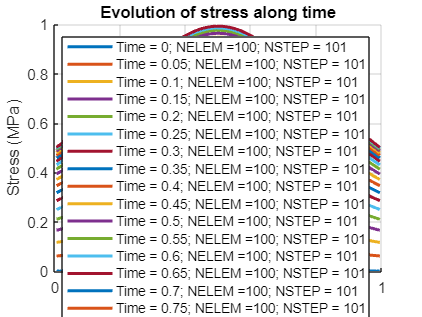

% Evolution of stresses along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Stress (MPa)')
title('Evolution of stress along time')
COOR_gauss = (COOR(CN(:,2))+  COOR(CN(:,1)))/2 ;
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR_gauss,STRESS_GLO(:,stepsPOST(i)),'LineWidth',2) ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
end
grid on
legend(hplot,LegendPlot)

legend('off')
legend

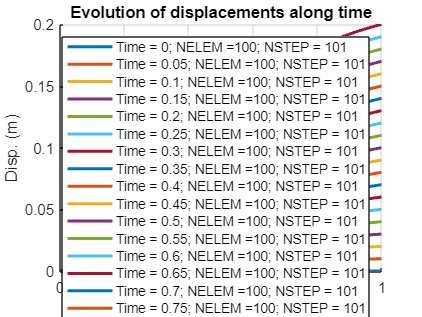


% Evolution of displacements along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Disp. (m)')
title('Evolution of displacements along time')
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR,d_GLO(:,stepsPOST(i)),'LineWidth',2) ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
end
grid on
legend(hplot,LegendPlot)

legend('off')
legend

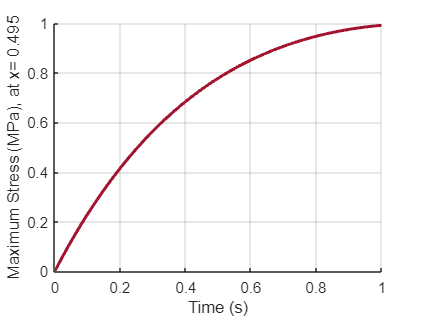




% Location of maximum stress

[stressEND,indELEM ]= max(STRESS_GLO(:,end)) ;
COOR_max_stress= COOR_gauss(indELEM) ;

figure
hold on
xlabel('Time (s)')
ylabel([['Maximum Stress (MPa), at x= ',num2str(COOR_max_stress)]]) ;
for i = 1:nsteps_plot
    h =   plot(TIMES,STRESS_GLO(indELEM,:),'LineWidth',2) ;
end
grid on

%legend(h,['NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)])

%legend('off')
%legend
